## HomeCreate the Robot Model

Create a Rigid Body Tree for Gen3 robot, set the home configuration and calculate the transformation at the home configuration:

gen3 = loadrobot("kinovaJacoJ2N6S200");%loads as a rigid body tree
gen3.DataFormat = 'column';%setting DataFormat = 'column' ensures that any joint configuration or velocity data you pass to functions like getTransform are represented as column vectors, rather than rows.
%q_home = [0 135 -90 0 -130 0 90 90]'*pi/180;%convert to radians always
q_home = [0 180 180 180 180 180 90 90]'*pi/180;
%%%%%%%%%%%%%%%%%%%%%
%NOTE: The last two are the grippers, they can 
%%%%%%%%%%%%%%%%%%%%%
eeName = 'j2n6s200_end_effector';%this is part of the robot, you can list this with some function
T_home = getTransform(gen3, q_home, eeName);%transform = getTransform(robot,configuration,bodyname) computes the transform that converts points in the bodyname frame to the robot base frame, using the specified robot configuration.
T_home

T_home =    -0.0000   -1.0000   -0.0000   -0.0000
   -0.5000    0.0000   -0.8660   -0.2595
    0.8660   -0.0000   -0.5000    0.8769
         0         0         0    1.0000


T_home(1:4,4) =  [0;0;0;1];%for some reason the the transformation blocks last column is converted to this
%implies row 1 to 4, column 4, we can also simply use : instead of 1:4 in this case

## **Visualize the Robot at Home Configuration**

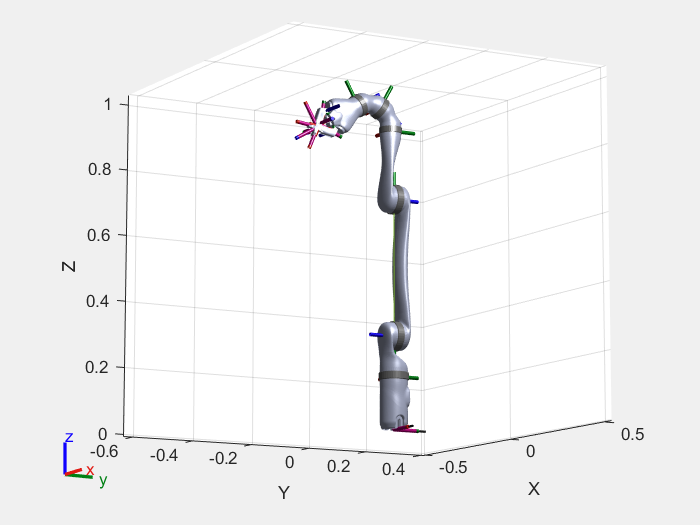

show(gen3,q_home);
axis auto;
view([60,-10]);

## **Define a Set of Waypoints Based on the Tool Position**

toolPositionHome = [0.3686    0.2085    0.2965];%results obtained from the T_home matrix before the 4th column changing
waypoints = toolPositionHome' + ... 
            [0 0 0 ; -0.1 0.2 0.2 ; -0.2 0 0.1 ; -0.1 -0.2 0.2 ; 0 0 0]';%5 locations in total, and all are averaged around current position

Define orientation.

The orientation is represented in Euler angles and the convention used is the Tait-Bryan, extrinsic ZYX.

Rotated wrt fixed axes, in the order of Z, Y and X. See animation of euler angles in wikipedia

orientations = [pi/2    0   pi/2;% I think this is for the end effector wrt ground, but in the simulation there was full down orientation too
               (pi/2)+(pi/4)      0   pi/2; 
                pi/2    0   pi;
               (pi/2)-(pi/4)       0    pi/2;
                pi/2    0   pi/2]';% 3x5 matrix NOTE: in matrices, you give data column by column, each ";" marks end of a column
%this might not be occurring because you choose data format to be columns
%in the first section

Define array of waypoint times.

waypointTimes = 0:7:28;%an array with 7 difference between each entry from 0 to 28, actually has 5 values now
ts = 0.25;
trajTimes = 0:ts:waypointTimes(end);%an array with 0.25 difference between each entry from 0 to 28

Define boundary conditions for velocity and acceleration.

waypointVels = 0.1 *[ 0  1  0;
                     -1  0  0;
                      0 -1  0;
                      1  0  0;
                      0	 1  0]';% 3x5 matrix due to taking Transpose `'` at the end.
%this might not be occurring because you choose data format to be columns
%in the first section

waypointAccels = zeros(size(waypointVels));%creates a matrix full of zeros at the same size as waypointVels
waypointAccelTimes = diff(waypointTimes)/4;%waypointTimes is an array and diff finds the difference
waypointAccelTimes

waypointAccelTimes =     1.7500    1.7500    1.7500    1.7500


## Create Inverse Kinematics Solver and Set Parameters

ik = inverseKinematics('RigidBodyTree',gen3);%an object associated with gen3
ikWeights = [1 1 1 1 1 1];%The vector [1 1 1 1 1 1] defines the relative importance (or weights) for each element in the 
% target pose: [x, y, z, roll, pitch, yaw]. The weights indicate how strictly the solver should aim to meet each of the pose requirements.
% In this case, all pose elements are equally weighted.
ikInitGuess = q_home';%the single quotes represents transpose and the home position is taking as a initial guess for non linear optimisation
ikInitGuess(ikInitGuess > pi) = ikInitGuess(ikInitGuess > pi) - 2*pi;%bringing any values above +pi to below
ikInitGuess(ikInitGuess < -pi) = ikInitGuess(ikInitGuess < -pi) + 2*pi;%bringing any values below -pi to below

## Set Plot and Display Waypoints

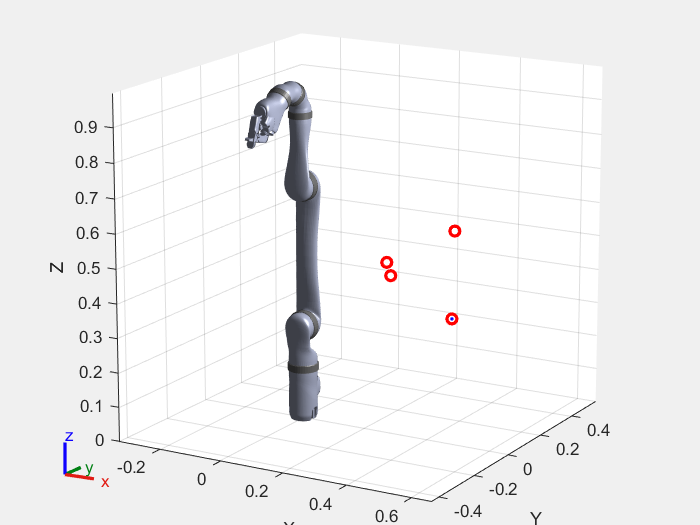

plotMode = 1; % 0 = None, 1 = Trajectory, 2 = Coordinate Frames
show(gen3,q_home,'Frames','off','PreservePlot',false);
hold on
if plotMode == 1
    hTraj = plot3(waypoints(1,1),waypoints(2,1),waypoints(3,1),'b.-');
end
plot3(waypoints(1,:),waypoints(2,:),waypoints(3,:),'ro','LineWidth',2);
axis auto;
view([30 15]);

## Solve the Inverse Kinematics for Each Waypoint

Set includeOrientation to zero if you do not want to define different orientation at different waypoints. When includeOrientation is set to false, a default orientation is used to compute the trajectory. 

includeOrientation = 0; %each column in waypoints represents a coordinate (end effector wants to reach)
numWaypoints = size(waypoints,2);%waypoints is a 3x5 matrix, the value of numWaypoints is 5 here since, size function returned the size of the 2nd dimension size(A,dim)
numJoints = numel(gen3.homeConfiguration);%numel is number of array elements function
jointWaypoints = zeros(numJoints,numWaypoints);%why needed when its only a bunch of zeros

**Why is jointWaypoints variable needed?**

Answer in the code below

for idx = 1:numWaypoints% a type of "for loop"
    if includeOrientation
        tgtPose = trvec2tform(waypoints(:,idx)') * eul2tform(orientations(:,idx)');
    else
        tgtPose = trvec2tform(waypoints(:,idx)') * eul2tform([pi/2 0 pi/2]); %#ok<UNRCH> this is the default
    end
    [config,info] = ik(eeName,tgtPose,ikWeights',ikInitGuess');
    jointWaypoints(:,idx) = config';
end
jointWaypoints

jointWaypoints =    -1.0006   -1.5336   -2.0113   -1.7862   -1.0006
    0.8244    1.3790    1.3081    3.9473    0.8244
    0.4637    1.1983    0.4154    5.8946    0.4637
    1.8060    2.1545    2.2795    3.8480    1.8060
    4.0846    4.3631    4.8220    2.2122    4.0846
    4.2247    3.9423    4.4060    3.5437    4.2247
    1.5708    1.5708    1.5708    1.5708    1.5708
    1.5708    1.5708    1.5708    1.5708    1.5708


## Generate a Trajectory in Joint Space using Interpolation

Select method of interpolation from trapezoidal velocity profiles, third-order polynomial, fifth-order polynomial or B-spline polynomial by modifying the variable trajType. 

trajType = 'trap';
switch trajType
    case 'trap'
        [q,qd,qdd] = trapveltraj(jointWaypoints,numel(trajTimes), ...
            'AccelTime',repmat(waypointAccelTimes,[numJoints 1]), ... 
            'EndTime',repmat(diff(waypointTimes),[numJoints 1]));
                            
    case 'cubic'
        [q,qd,qdd] = cubicpolytraj(jointWaypoints,waypointTimes,trajTimes, ... 
            'VelocityBoundaryCondition',zeros(numJoints,numWaypoints));
        
    case 'quintic'
        [q,qd,qdd] = quinticpolytraj(jointWaypoints,waypointTimes,trajTimes, ... 
            'VelocityBoundaryCondition',zeros(numJoints,numWaypoints), ...
            'AccelerationBoundaryCondition',zeros(numJoints,numWaypoints));
        
    case 'bspline'
        ctrlpoints = jointWaypoints; % Can adapt this as needed
        [q,qd,qdd] = bsplinepolytraj(ctrlpoints,waypointTimes([1 end]),trajTimes);
        % Remove the first velocity sample
        qd(:,1) = zeros (7,1);    
    otherwise
        error('Invalid trajectory type! Use ''trap'', ''cubic'', ''quintic'', or ''bspline''');
end

## Visualize the Solution

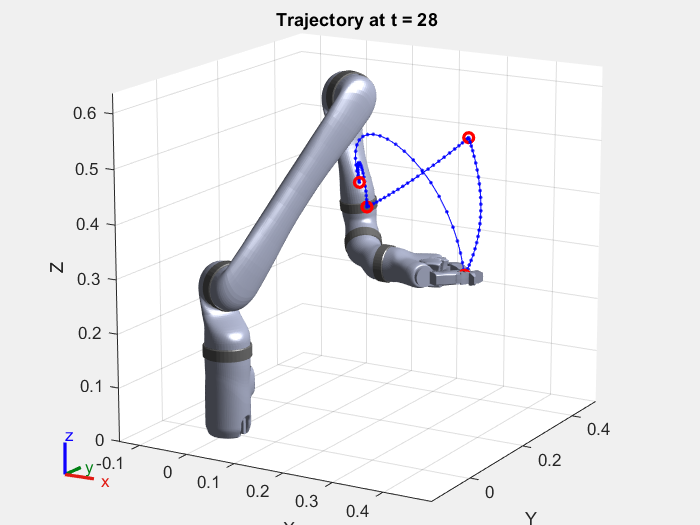

for idx = 1:numel(trajTimes)  
 
    config = q(:,idx)';
    
    % Find Cartesian points for visualization
    eeTform = getTransform(gen3,config',eeName);
    if plotMode == 1
        eePos = tform2trvec(eeTform);
        set(hTraj,'xdata',[hTraj.XData eePos(1)], ...
                  'ydata',[hTraj.YData eePos(2)], ...
                  'zdata',[hTraj.ZData eePos(3)]);
    elseif plotMode == 2
        plotTransforms(tform2trvec(eeTform),tform2quat(eeTform),'FrameSize',0.05);
    end
 
    % Show the robot
    show(gen3,config','Frames','off','PreservePlot',false);
    title(['Trajectory at t = ' num2str(trajTimes(idx))])
    drawnow   
    
end